Team 1:

Zachary Cohen (*40200367*)

Tyler Kassis (*40231047*)

Jason Manuele (*40246711*)

Jessice Socher (*40241254*)

Pascal Ypperciel (*40210921*)

**COEN/ELEC 390 - Computer Simulation**

        This computer simulation will commence with some Idea Generation and Selection simulations, which will be used to refine the algorithms needed to process the data taken from the handheld material strength tester.  Once the most optimal algorithm is chosen for each function, the next stage would be to perform Detailed Design simulations.  This type of simulation will allow the team to solidify the algorithms being integrated into the product by finalizing any variable parameters present in the application's methods.  Once a prototype of the product has been created, the team have the opportunity to conduct Testing and Validation simulations to verify whether the product behaves as it should and to further clarify any doubt as to whether the data being taken from the sensors is being manipulated correctly.  Nevertheless, before completing these simulations, two benchmarks must be created for comparison, namely the "theoretical" and "simulated" benchmarks.  The former will consist of theoretical values being used to simulate the compressive and tesnile strengths and strains of different materials, while the latter will consist of the same simulations, this time with "dummy data". 

clc; clear; close all;

*Idea Generation and Selection (***SIM-1***)*

**Theoretical Benchmark**

        Firstly, all important variables must be defined for the theretical simulation.  These values must be taken from known values for materials that will closely resemble those used for the simulated benchmark and subsequent simulations. These equations are first displayed utilizing an example of a material with its known Youngès Modulus (ie: steel) and then will be applied in the Algorithm Section with the tested material. 

## Define Material and Setup Parameters

% Cross-Sectional Areas
A_Steel = 0.01;  % Cross-sectional area of sample (m^2)

% Initial Lengths
L_0_Steel = 0.05; % Initial height of the Steel sample (m)

% Young's Moduli
Y_Steel = 200e6; % True Young's modulus of the Steel sample (Pa)

% Spring Coefficients
k_Steel = (Y_Steel * A_Steel)/L_0_Steel;

% Yield Strengths
yield_strength = 250e6; % Yield strength (Pa)

% Fracture Strain
fracture_strain = 0.02; % Fracture strain (beyond this, material breaks)

% Timeline
time = linspace(0, 10, 150); % 10 seconds test duration, 150 points

Compression:

        The value for the Engineering Compressive Stress is defined as *the force that is responsible for the deformation of the material such that the volume of the material reduces *[1].  The formula expressing the theoretical value of this metric is given as:

        
$$\sigma = \frac{F}{A_0}$$


        In this equation, $\sigma $ is the Engineering Compressive Stress in Pascals [$Pa$] or Newton per Meter Squared [$N/m^2$], $F$ is the Compressive Force applied to the object in Newtons $[N]$, and $A_0$ is the original cross-sectional area to which the compressive force is applied in Meters Squared [$m^2$] [3].    Given all of this information, the theoretical Compressive Stress is:

% Engineering Compressive Stress
stress = zeros(1, length(time));

compressive_force_min = input("what should the minimum amount of compressive force be, in Newtons? ")

compressive_force_min = 500

compressive_force_max = input("What should the maximum amount of compressive force be, in Newtons? ")

compressive_force_max = 200000

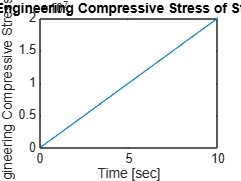


compressive_force = linspace(compressive_force_min, compressive_force_max, 150);

for i = 1:(length(time))
    stress(i) = compressive_force(i)/A_Steel;
end

% Plotting the Engineering Compressive Stress VS Time
plot(time, stress);
xlabel("Time [sec]");
ylabel("Engineering Compressive Stress [Pa]");
title("Engineering Compressive Stress of Steel");

        The value the Engineering Compressive Strain is defined as *the deformation in a solid due to the application of compressive stress *[4].  The formula expressing the theoretical value of this metric is given as:

        
$$\epsilon = \frac{\Delta L}{L_0} = \frac{L - L_0}{L_0}$$


        In this equation, $\epsilon$ is the Engineering Compressive Strain, $L$ is the deformed length of the material, in Meters [$m$], $L_0$ is the original length of the material, in Meters [$m$], and $\Delta L$ is the change in material's length, in Meters [$m$].  Given all of this information, the theoretical Compressive Strain is:

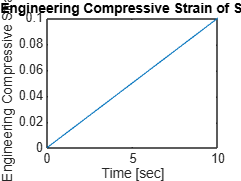

% Engineering Compressive Strain
strain = zeros(1, length(time));

% The length of the steel as time elapses.
L_Steel = zeros(1, length(time));
for i = 1:(length(time))
    L_Steel(i) = L_0_Steel - (compressive_force(i)/k_Steel);
    strain(i) = abs((L_Steel(i) - L_0_Steel)/L_0_Steel);
end

% Plotting the Engineering Compressive Strain VS Time
plot(time, strain);
xlabel("Time [sec]");
ylabel("Engineering Compressive Strain");
title("Engineering Compressive Strain of Steel");

        Although the values above are normally used to express Compressive Stress and Strain, these are only approximations ot their true values. True Compressive Stress is defined as *the value of stress in the material considering the actual area* [2].  The formula expressing the theoretical value of this metric is given as:

        
$$\widetilde\sigma = \sigma\cdot(1 + \epsilon)$$


        In this equation, $\widetilde\sigma$ is the True Compressive Strength, $\sigma $ is the Engineering Compressive Stress in Pascals [$Pa$] and $\epsilon$ is the Engineering Compressive Strain. With this formula, one may convert between Engineering and True Compressive Strain by using the relation above.  On the other hand, the True Compressive Strain is defined as *the summation of strain with the change in length calculated as infintesimally small increments divide amount the entire material* [2].  The formula expressing the theoretical value of this metric is given as:


$$\widetilde\epsilon =\int_{L_0}^{L}\frac{dL}{L} = ln(\frac{L}{L_0}) = ln(1 + \epsilon)$$


        In this equation, $\widetilde\epsilon$is the True Compressive Strain, $\epsilon$ is the Engineering Compressive Strain, $L$ is the compresssed length of the material, in Meters [$m$], and $L_0$ is the original length of the material, in Meters [$m$].  Alternatively, the True Compressive Strain can be claculated as follows:


$$\widetilde\epsilon = ln(\frac{A_0}{A})$$


        In this equation, $\widetilde\epsilon$is the True Compressive Strain, $A_0$ is the original cross-sectional area of the material, in Meters Squared [$m$], and $A$ is the compressed cross-sectional area, in Meters Squared [$m$].  Given all of this information, the theoretical True Compressive Stress and Strain  are:

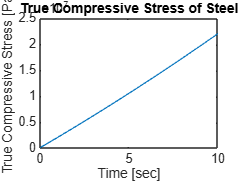

% True Compressive Stress
stress_true = stress.*(1 + strain);

% Plotting the True Compressive Stress VS Time
plot(time, stress_true);
xlabel("Time [sec]");
ylabel("True Compressive Stress [Pa]");
title("True Compressive Stress of Steel");

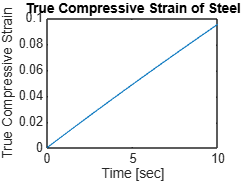


% True Compressive Strain
strain_true = log(1 + strain);

% Plotting the True Compressive Strain VS Time
plot(time, strain_true);
xlabel("Time [sec]");
ylabel("True Compressive Strain");
title("True Compressive Strain of Steel");

Tension: (***Note:**** In general, Tensile Stress and Strain are reprsented using the same formulas.  However, the direction of the applied force is generally in the opposite direction.*)

        The value for Engineering Tensile Stress is defined as *the pulling force or elongation of a material* [2], [5], [6].  The formula expressing the theoretical value of this metric is given as:

        
$$\sigma = \frac{F}{A_0}$$


        In this equation, $\sigma $ is the Engineering Tensile Stress in Pascals [$Pa$] or Newtons per Meters Squared [$N/m^2$], $F$ is the Tensile Force applied to the object in Newtons $[N]$, and $A_0$ is the original cross-sectional area to which the tensile force is applied in Meters Squared [$m^2$] [3].  Given all of this information, the theoretical Tensile Stress  is:

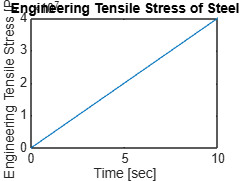

% --- Engineering Tensile Stress ---
t_stress = zeros(1, length(time));

t_force_min = input("What should the minimum amount of tensile force be, in Newtons? ");
t_force_max = input("What should the maximum amount of tensile force be, in Newtons? ");

t_force = linspace(t_force_min, t_force_max, 150);

for i = 1:length(time)
    t_stress(i) = t_force(i) / A_Steel;
end

% Plot Engineering Tensile Stress vs Time
figure;
plot(time, t_stress);
xlabel("Time [sec]");
ylabel("Engineering Tensile Stress [Pa]");
title("Engineering Tensile Stress of Steel");

        The value the Engineering Tensile Strain is defined as *how much the material is being stretched or elongated by the tensile stress *[7].  The formula expressing the theoretical value of this metric is given as:

        
$$\epsilon = \frac{\Delta L}{L_0} = \frac{L - L_0}{L_0}$$


        In this equation, $\epsilon$ is the Engineering Tensile Strain, $L$ is the deformed length of the material, in Meters [$m$], $L_0$ is the original length of the material, in Meters [$m$], and $\Delta L$ is the change in material's length, in Meters [$m$].  Given all of this information, the theoretical Tensile Strain is:

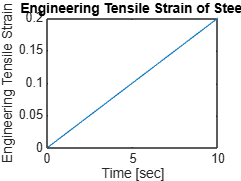

% --- Engineering Tensile Strain ---
t_strain = zeros(1, length(time));

% Length of the steel as time elapses
t_L_Steel = zeros(1, length(time));

for i = 1:length(time)
    t_L_Steel(i) = L_0_Steel + (t_force(i) / k_Steel); % Elongation in tension
    t_strain(i) = (t_L_Steel(i) - L_0_Steel) / L_0_Steel;
end

% Plot Engineering Tensile Strain vs Time
figure;
plot(time, t_strain);
xlabel("Time [sec]");
ylabel("Engineering Tensile Strain");
title("Engineering Tensile Strain of Steel");

        Although the values above are normally used to express Tensile Stress and Strain, these are only approximations ot their true values. True Tensile Stress is defined as *the value of stress in the material considering the actual area* [2].  The formula expressing the theoretical value of this metric is given as:

        
$$\widetilde\sigma = \sigma\cdot(1 + \epsilon)$$


        In this equation, $\widetilde\sigma$ is the True Tensile Strength, $\sigma $ is the Engineering Tensile Stress in Pascals [$Pa$] and $\epsilon$ is the Engineering Tensile Strain. With this formula, one may convert between Engineering and True Tensile Strain by using the relation above.  On the other hand, the True Tensile Strain is defined as *the summation of strain with the change in length calculated as infintesimally small increments divide amount the entire material* [2].  The formula expressing the theoretical value of this metric is given as:


$$\widetilde\epsilon =\int_{L_0}^{L}\frac{dL}{L} = ln(\frac{L}{L_0}) = ln(1 + \epsilon)$$


        In this equation, $\widetilde\epsilon$is the True Tensile Strain, $\epsilon$ is the Engineering Tensile Strain, $L$ is the elongated length of the material, in Meters [$m$], and $L_0$ is the original length of the material, in Meters [$m$].  Alternatively, the True Tensile Strain can be claculated as follows:


$$\widetilde\epsilon = ln(\frac{A_0}{A})$$


        In this equation, $\widetilde\epsilon$is the True Tensile Strain, $A_0$ is the original cross-sectional area of the material, in Meters Squared [$m$], and $A$ is the elongated cross-sectional area, in Meters Squared [$m$].  Given all of this information, the theoretical True Tensile Stress and Strain  are:

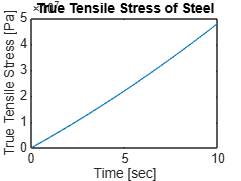

% --- True Tensile Stress ---
t_stress_true = t_stress .* (1 + t_strain);

% Plot True Tensile Stress vs Time
figure;
plot(time, t_stress_true);
xlabel("Time [sec]");
ylabel("True Tensile Stress [Pa]");
title("True Tensile Stress of Steel");

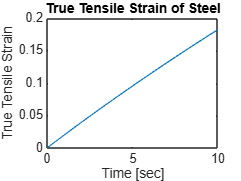


% --- True Tensile Strain ---
t_strain_true = log(1 + t_strain);

% Plot True Tensile Strain vs Time
figure;
plot(time, t_strain_true);
xlabel("Time [sec]");
ylabel("True Tensile Strain");
title("True Tensile Strain of Steel");

Young's Modulus:

        The Elastic modulus of a material is defined as *the ratio of stress to strain* [6].  Moreover, the Young's Modulus of a material is considered the Elastic Modulus of a solid material when it's length is changed through an applied force.  This modulus is defined as *the resistance of a solid to a change in its length* [6].  As such, the formula expressing the theoretical value of this metric is the following:


$$Y = \frac{Stress}{Strain} = \frac{\frac{F}{A_0}}{\frac{\Delta L}{L_0}}$$


        In this equation, $Y$is the Young's Modulus in Newtons per Meters Squared $[N/m^2]$, $F$ is the Compressive or Tensile Force applied to the object in Newtons $[N]$, $A_0$ is the original cross-sectional area to which the compressive or tensile force is applied in Meters Squared [$m^2$], $L_0$ is the original length of the material, in Meters [$m$], and $\Delta L$ is the change in material's length, in Meters [$m$].  Given all of this information, the Young's moduli  are the following:

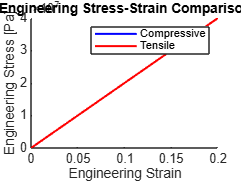

% --- Engineering Stress vs. Strain (Tensile vs. Compressive) ---
figure; hold on;
plot(strain, stress, 'b', 'LineWidth', 1.5); % Compressive Stress-Strain
plot(t_strain, t_stress, 'r', 'LineWidth', 1.5); % Tensile Stress-Strain

xlabel("Engineering Strain");
ylabel("Engineering Stress [Pa]");
title("Engineering Stress-Strain Comparison");
legend("Compressive", "Tensile");
axis auto;
hold off;

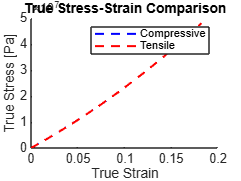


% --- True Stress vs. True Strain (Tensile vs. Compressive) ---
figure; hold on;
plot(strain_true, stress_true, 'b--', 'LineWidth', 1.5); % Compressive True Stress-Strain
plot(t_strain_true, t_stress_true, 'r--', 'LineWidth', 1.5); % Tensile True Stress-Strain

xlabel("True Strain");
ylabel("True Stress [Pa]");
title("True Stress-Strain Comparison");
legend("Compressive", "Tensile");
axis auto;
hold off;


% --- Engineering vs. True Young's Modulus (Tensile & Compressive) ---
figure; hold on;
plot(strain, stress, 'b', 'LineWidth', 1.5); % Engineering Compressive
plot(strain_true, stress_true, 'b--', 'LineWidth', 1.5); % True Compressive
plot(t_strain, t_stress, 'r', 'LineWidth', 1.5); % Engineering Tensile
plot(t_strain_true, t_stress_true, 'r--', 'LineWidth', 1.5); % True Tensile

xlabel("Strain");
ylabel("Stress [Pa]");
title("Young's Modulus Comparison");
legend("Engineering Compressive", "True Compressive", "Engineering Tensile", "True Tensile");
axis auto;
hold off;


Ultimate Strength [6]:

        The Ultimate Strength of a material is defined as *the maximum stress that an object can withstand*.  If the stress (*Compressive or Tensile*) surpasses this value, this will cause the material to enter the "Breakpoint" region and ultimately fracture or break.

Elastic Limit [8]:

        The Elastic Limit is defined as the theoretical beginning of the Plastic Deformation Region, based on the properties of the matrial being observed.  Inside the elastic region, the material undergoes Elastic Deformation, wherein the material will re-assume its original shape when the load has been removed. Contrarily, Plastic Deformation will cause the material’s shape to change permanently.

Hooke's Law [9], [10]:

        Within the Elastic Region, the deformation is governed by Hooke’s Law, which states that *the force applied to a spring will scale linearly by a distance "x", by which the spring is compressed or stretched, according to some Spring Constant "k"*.  Hooke's Law is defined by the following formula: 


$$F_s = -k\times\Delta x$$


        In the context of the strength testing of materials, Hooke’s Law will be used to determine stress from a piston on our test material, and will subsequently explain the absorption of energy by a material under stress inside of its elastic modulus.

Ductile Failure (i.e., *Yield*) [8]:

        A Ductile Failure is defined as *a type of failure seen in malleable materials characterized by extensive plastic deformation or necking*. Normally occurring before the actual failure of the material, there is absorption of massive amounts of energy and slow propagation before the fracture occurs.  Several parameters, including temperature, loading rate, and state of stress, can all affect the fracture of a material.  On the other hand, a Ductile Rupture is known to be the *failure of a highly ductile material, wherein a material will be pulled apart instead of cracking*.

Offset Method [11]:

        The Offset Method is defined as *the most common method for determining the yield point*. To find this yield point, a line is drawn parallel to the initial linear portion of the stress-strain curve but offset by a certain amount of strain (*e.g., 0.2%, the industry standard*). The point at which this line intersects the stress-strain curve is defined as the yield point.

**Simulated Benchmark**

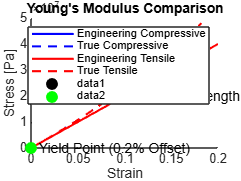

% Example: Finding Ultimate Strength (Max Engineering Stress)
[ultimate_strength, idx_ultimate] = max(stress);
ultimate_strain = strain(idx_ultimate);

% Example: Finding Yield Point using 0.2% Offset Method
offset_strain = 0.002; % 0.2% strain
offset_line = @(x) (x - offset_strain) * (max(stress) / max(strain));
idx_yield = find(stress >= offset_line(strain), 1);
yield_stress = stress(idx_yield);
yield_strain = strain(idx_yield);

% Mark Points on Graph
hold on;
plot(ultimate_strain, ultimate_strength, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8);
text(ultimate_strain, ultimate_strength, '  Ultimate Strength', 'FontSize', 10);

plot(yield_strain, yield_stress, 'go', 'MarkerFaceColor', 'g', 'MarkerSize', 8);
text(yield_strain, yield_stress, '  Yield Point (0.2% Offset)', 'FontSize', 10);
hold off;

***Algorithm Development***

    In this section, the data utilized for the simulation of a Car Sponge was exported from the CAT Tester prototype as the "Dummy Data" for the experiment. The force, displacement and time was exported to a csv file in "coen390sim1.csv" and the Young's Modulus of the material was found teoretically utilizing the equations shown above. This algorithm simulation is an example of how the mathematics will be implemented in the CAT Tester. The data received is interpreted and anaylzed, and then stored in a database, which is simulated with the "processed_data" file. 

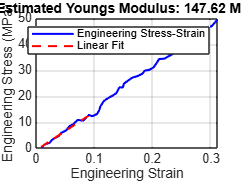

% Load Data
data = readmatrix('coen390sim1.csv');

time_data = data(:, 1);          % Time (s)
displacement = data(:, 2);     % Total distance (mm)
force = data(:, 3);              % Force (N)

% Define Material & Sample Properties
L_initial = 50;    % Initial length of test material (mm)
Area = 10;    % Initial cross-sectional area (mm^2)

% Compute Engineering Stress & Strain
strain_engineering = displacement / L_initial;
stress_engineering = force / Area;

% Estimate Young's Modulus (first 10% strain data)
linear_idx = strain_engineering < 0.1;  % Linear region assumed up to 10% strain
p = polyfit(strain_engineering(linear_idx), stress_engineering(linear_idx), 1);
E_estimated = p(1);  % Young’s modulus (slope of linear fit)

% Compute Offset Method (0.2% Offset Line)
offset_strain = strain_engineering + 0.002;
offset_stress = E_estimated * offset_strain; % Linear offset using Young's modulus

% Find Yield Stress (Intersection Point)
idx_yield = find(stress_engineering >= offset_stress, 1); % First intersection index
yield_stress = stress_engineering(idx_yield);
yield_strain = strain_engineering(idx_yield);

% Compute True Stress & True Strain
true_strain = log(1 + strain_engineering);
true_stress = stress_engineering .* (1 + strain_engineering);

% Plot Engineering Stress-Strain Curve with Young's Modulus
figure;
plot(strain_engineering, stress_engineering, 'b', 'LineWidth', 1.5);
hold on;
plot(strain_engineering(linear_idx), polyval(p, strain_engineering(linear_idx)), 'r--', 'LineWidth', 1.5);
legend('Engineering Stress-Strain', 'Linear Fit');
xlabel('Engineering Strain'); ylabel('Engineering Stress (MPa)');
title(['Estimated Youngs Modulus: ', num2str(E_estimated, '%.2f'), ' MPa']);
grid on;

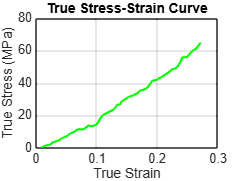


% Plot True Stress-Strain Curve
figure;
plot(true_strain, true_stress, 'g', 'LineWidth', 1.5);
xlabel('True Strain'); ylabel('True Stress (MPa)');
title('True Stress-Strain Curve');
grid on;

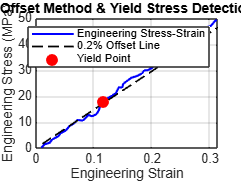


% Plot Offset Method and Yield Point
figure;
plot(strain_engineering, stress_engineering, 'b', 'LineWidth', 1.5);
hold on;
plot(offset_strain, offset_stress, 'k--', 'LineWidth', 1.2); % Offset method
plot(yield_strain, yield_stress, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r'); % Yield point
legend('Engineering Stress-Strain', '0.2% Offset Line', 'Yield Point');
xlabel('Engineering Strain'); ylabel('Engineering Stress (MPa)');
title('Offset Method & Yield Stress Detection');
grid on;


% Save Processed Data (Simulating the Data Path, storing calculated data in DB)
processed_data = [time_data, total_distance, displacement, strain_engineering, stress_engineering, true_strain, true_stress];
writematrix(processed_data, 'processed_data.csv');
disp('Processed data saved as processed_data.csv');

Processed data saved as processed_data.csv


*Detailed Design (***SIM-2***) (To do in Sprint 2)*

*Testing and Validation (***SIM-3***) (To do in Sprint 2)*

*References*

`[1]    BYJU'S, “What Is Compressive Stress? - Definition, Formula, Unit, Dimension,” BYJU’S. https://byjus.com/physics/compressive-stress/ (accessed Mar. 09, 2025). `

`[2]    MechaniCalc, “Mechanical Properties of Materials | MechaniCalc,” Mechanicalc.com. https://mechanicalc.com/reference/mechanical-properties-of-materials (accessed Mar. 09, 2025). `

`[3]    isaac, “Isaac Physics,” Isaac Physics. https://isaacphysics.org/concepts/cp_stress_strain_elastic (accessed Mar. 09, 2025). `

`[4]    BYJU'S, “What Is Stress and Strain? Stress-Strain Curve, SI Units,” BYJU’S. https://byjus.com/physics/stress-and-strain/ (accessed Mar. 09, 2025). `

`[5]    ScienceFacts.net, “Tensile Stress: Definition, Formula, and Example Problems,” Science Facts, Feb. 20, 2025. https://www.sciencefacts.net/tensile-stress.html (accessed Mar. 09, 2025). `

`[6]    J. Pan, “Statics Ad Engineering Physics - Statics and Strength of Materials,” 2022. `

`[7]    B. Ohi and Materials Science & Engineering Student, “True Stress-Strain Vs Engineering Stress-Strain,” Materials Science & Engineering Student, Mar. 01, 2022. https://msestudent.com/true-stress-strain-vs-engineering-stress-strain/ (accessed Mar. 09, 2025). `

`[8]    Wikipedia, “Material Failure Theory,” Wikipedia, Jun. 14, 2021. https://en.wikipedia.org/wiki/Material_failure_theory (accessed Mar. 09, 2025). `

`[9]    A. B. Zavatsky, “P4 Stress and Strain - Lecture 1 - Tension and Compression.”`

`[10]    “2-1 Hooke’s Law Chapter 12 -Simple Harmonic Motion Page 12 -2.” [11]   M. M. Costa and Biopedi, “Compression Testing: Exploring Methods, Applications, and Benefits,” Biopdi, Jul. 13, 2020. https://biopdi.com/compression-testing/ (accessed Mar. 09, 2025).`